## Model of Bicycle without Gyroscope

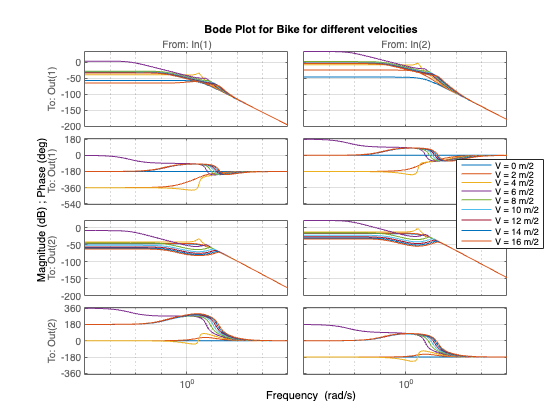

clear
clc

% Matrices from Schwab et Al.
M = [80.817 2.319;2.319 0.298];
C1 = [0 33.866;-0.85 1.685];
K2 = [0 76.597;0 2.654];
K0 = [-80.95 -2.6;-2.6 -0.803];

V = 0:2:16; % m/s
% v = 6; % m/s
g = 9.81; % m/s^2

dt = 0.1;
t = 0:dt:20; % s

Systems = struct;

for i = 1:length(V)
    v = V(i);
    A = [zeros(2,2) eye(2);
        -inv(M)*(v^2*K2+g*K0) -inv(M)*v*C1];
    B = [zeros(2,2); inv(M)];
    C = [eye(2) zeros(2,2)];
    D = 0;
    Sys = ss(A,B,C,D);
    Systems(i).system = Sys;
end
bode(Systems(1).system, Systems(2).system, Systems(3).system, Systems(4).system, Systems(5).system, Systems(6).system,  Systems(7).system, Systems(8).system, Systems(9).system)
title('Bode Plot for Bike for different velocities')
grid on
legend('V = 0 m/2','V = 2 m/2','V = 4 m/2','V = 6 m/2','V = 8 m/2','V = 10 m/2','V = 12 m/2','V = 14 m/2','V = 16 m/2',"Position", [0.81687,0.429,0.15179,0.17262])

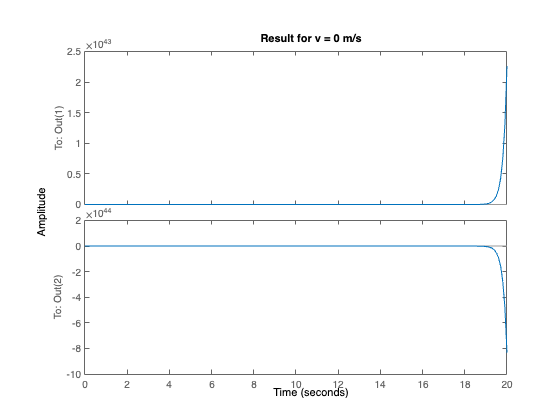



T_steer = 1; % Nm
T_roll = 0; % Nm
T = zeros(2,length(t));
T(1,1) = T_steer;
T(1,2) = T_roll;

lsim(Systems(1).system,T,t)
title("Result for v = 0 m/s")

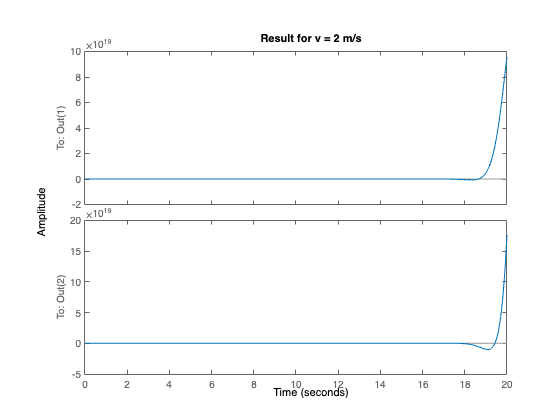

lsim(Systems(2).system,T,t)
title("Result for v = 2 m/s")

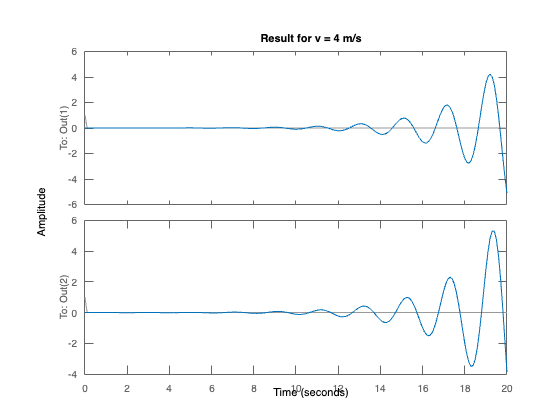

lsim(Systems(3).system,T,t)
title("Result for v = 4 m/s")

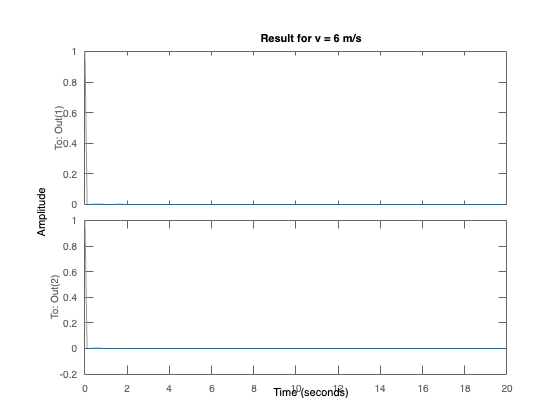

lsim(Systems(4).system,T,t)
title("Result for v = 6 m/s")

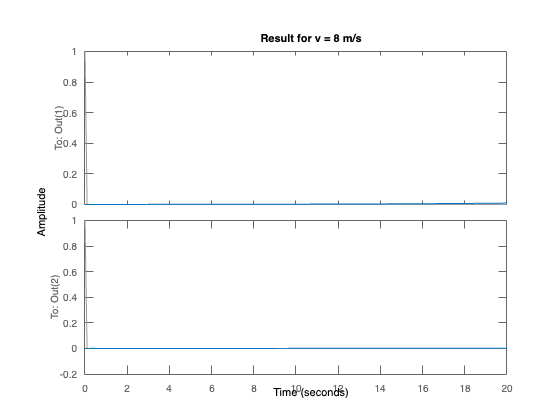

lsim(Systems(5).system,T,t)
title("Result for v = 8 m/s")

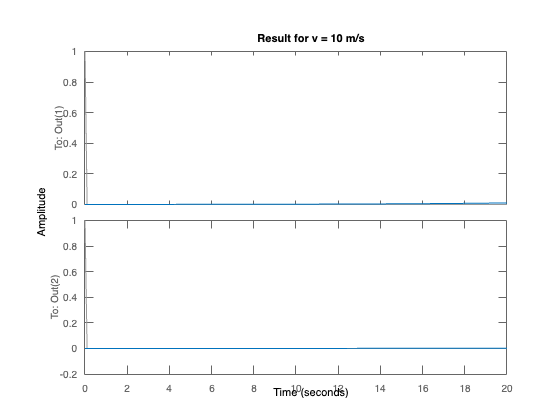

lsim(Systems(6).system,T,t)
title("Result for v = 10 m/s")

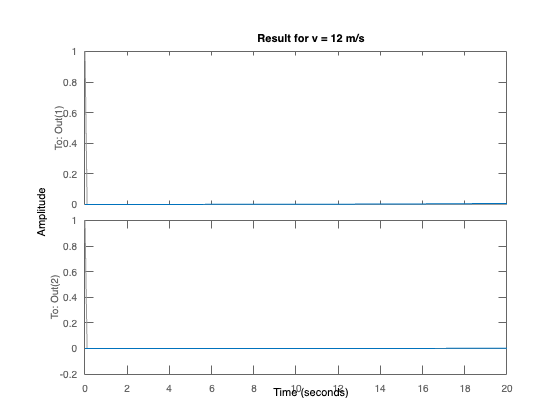

lsim(Systems(7).system,T,t)
title("Result for v = 12 m/s")

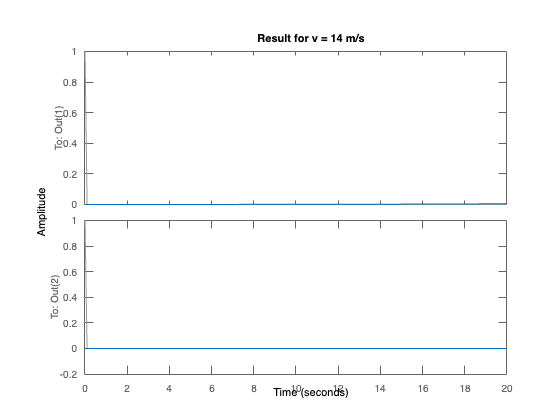

lsim(Systems(8).system,T,t)
title("Result for v = 14 m/s")

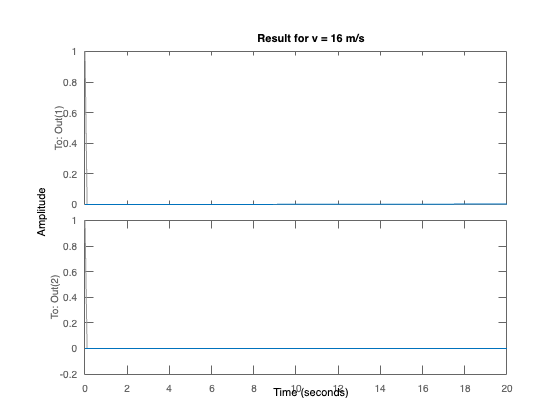

lsim(Systems(9).system,T,t)
title("Result for v = 16 m/s")